clearvars

%{
The model includes following commands:

CMUT(R_pl, H_pl, D_w, H_ins_l, H_gap) - Creation of the object of CMUT type
    1) Radius of the cell [um]
    2) Height of the plate [um]
    3) Width of the wall (pillars) [um]
    4) Height of the insulation layer [um]
    5) Height of the gap [um]


Find_Lumped_Parameters(obj, V_dc) - Calculation of the lumped parameters
    1) Object of CMUT type
    2) DC voltage [V]


Find_Eigenvalues(obj) - Calculation of the eigenfrequencies and eigenmodes
    1) Object of CMUT type


Plot_Eigenmodes(obj, j, k, dimension) - Demonstration of the eigenfrequencies and eigenmodes
    1) Object of CMUT type
    2) Number of node circles [1, 2, 3, 4, 5, 6]
    3) Number of node diameters [1, 2, 3]
    4) Type of the plot ('1D' or '2D')


Find_Response(obj, V_dc, V_ac, f) - Calculation of a response to the applied voltage
    1) Object of CMUT type
    2) DC voltage [V]
    3) AC voltage [V]
    4) AC frequency [MHz] (as a single value or a range of values)


Plot_Response(obj, type, dimension) - Demonstration of the mehcanical response
    1) Object of CMUT type
    2) Type of the load ('Static', 'Dynamic' or 'Sweep')
    3) Type of the plot ('1D' or '2D')

    Existence of "type" parameter depends on the calculated Find_response cases:
    1)'Static' for a case with non-zero DC voltage, but zero AC voltage
    2)'Dynamic' for a case with non-zero DC voltage and non-zero AC voltage
    3)'Sweep' for a case with non-zero DC voltage, non-zero AC voltage and
    a range of AC frequencies


Find_FR(obj, type, Nx, Ny, phase, d, medium, r0, direction) - Calculation of the acoustic field
    1) Object of CMUT type
    2) Type of the load ('Dynamic' or 'Sweep')
    3) Number of cells along x-direction
    4) Number of cells along y-direction
    5) Array with phase shifts for cells of size (Nx, Ny)
    6) Distance between the cells in the array [um]
    7) Medium ('air' or 'water')
    8) Radius from the center of the CMUT array to calculate the acoustic field [um]
    9) Direction of the normal vector for the radiation pattern field as a vector


Plot_FR(obj, type) - Demonstration of the acoustical response
    1) Object of CMUT type
    2) Type of the load ('Dynamic' or 'Sweep')

    Existence of "type" parameter depends on the calculated Find_FR cases:
    1)'Dynamic' for a case of 'Dynamic' type
    2)'Sweep' for a case of 'Sweep' type
%}

# Multiphysical model of CMUT array based on modal decomposition and the Rayleigh integral

## Creation of an object

CMUT1 = CMUT(70, 1.8, 15, 0.2, 0.3);

disp(['Collapse voltage is ', num2str(CMUT1.V_collapse), ' V for CMUT1'])

Collapse voltage is 29.8914 V for CMUT1


## Lumped parameters

#### Calculation of lumped parameters

V_dc_1 = 24;

CMUT1 = Find_Lumped_Parameters( CMUT1, V_dc_1); % Object, V_dc, Set of corrective coefficients

disp(['Capacity is ', num2str(1e12*CMUT1.C), ' pf'])

Capacity is 1.2751 pf


disp(['Charge is ', num2str(1e12*CMUT1.Q), ' pC'])

Charge is 30.6019 pC


disp(['Force is ', num2str(1e6*CMUT1.F), ' uN'])

Force is 270.1953 uN


disp(['Displacement is ', num2str(1e9*CMUT1.Disp_max), ' nm'])

Displacement is 55.4748 nm


disp(['Eigenfrequency is ', num2str(1e-6*CMUT1.f_1), ' MHz'])

Eigenfrequency is 2.3781 MHz


disp(['Shifted by DC voltage eigenfrequency is ', num2str(1e-6*CMUT1.f_1_shifted), ' MHz'])

Shifted by DC voltage eigenfrequency is 2.3611 MHz


## Eigenfrequencies and Eigenmodes

#### Solving eigenvalue problem

CMUT1 = Find_Eigenvalues(CMUT1);


#### Shape of an eigenmode

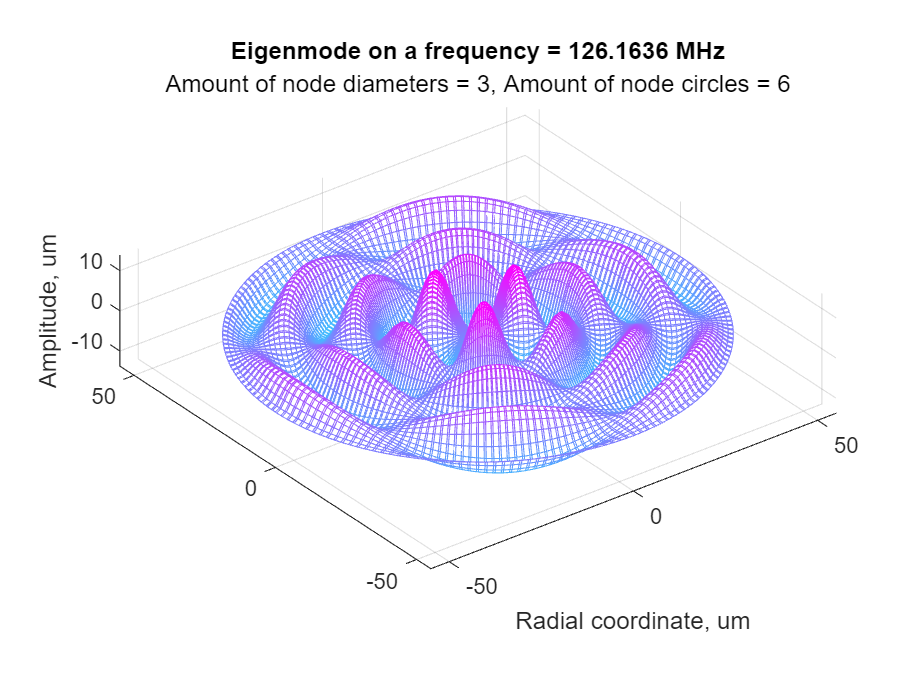

Plot_Eigenmodes(CMUT1, 6, 3, '2D');

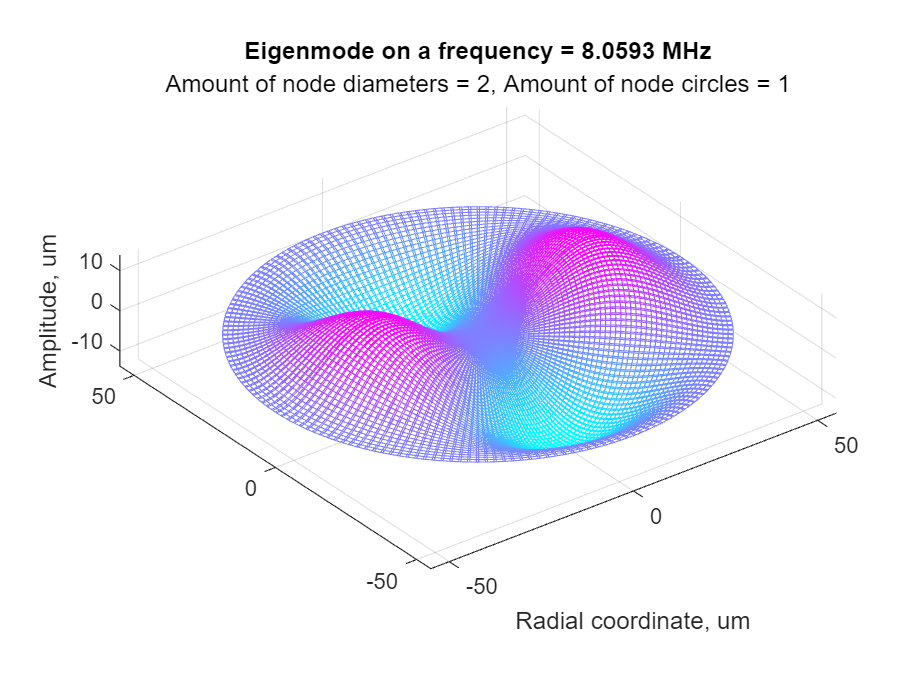

Plot_Eigenmodes(CMUT1, 1, 2, '2D');


disp(['True eigenfrequencies are ', num2str(1e-6*CMUT1.Eigenfrequencies(1,:)), ' MHz'])

True eigenfrequencies are 2.36063      9.19017      20.5898      36.5526      57.0773      82.1636 MHz


## Mechanical response to an arbitrary excitation

#### DC case

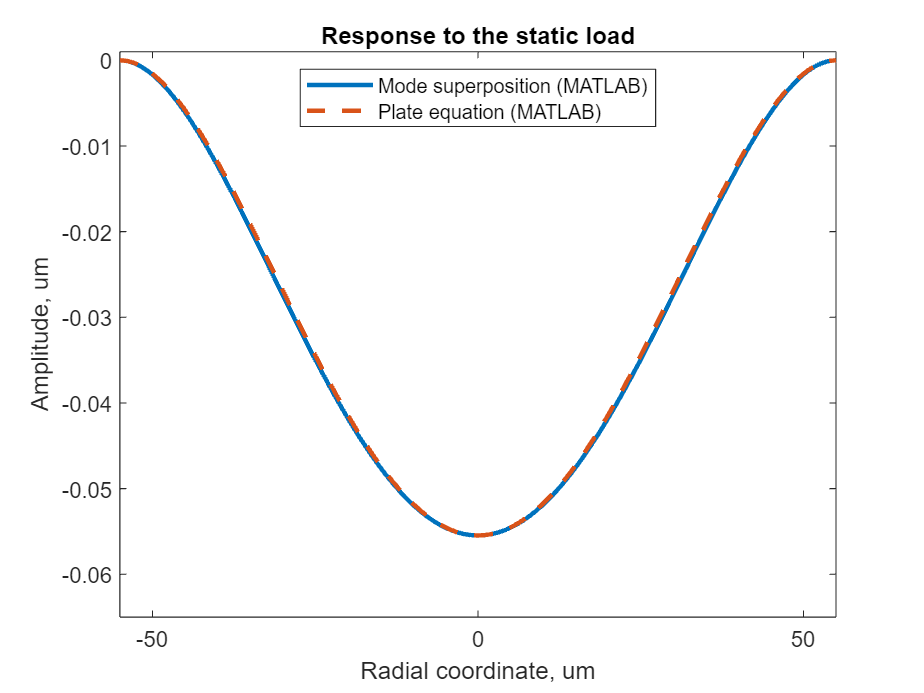

CMUT1 = Find_Response(CMUT1, V_dc_1, 0, 0);

plot(1e6*CMUT1.r,-1e6*CMUT1.Amplitude_Response.static.amp(:,1), 'LineWidth', 2)
hold on
plot(1e6*CMUT1.r,-1e6*CMUT1.Disp_static, '--', 'LineWidth', 2)
title('Response to the static load')
xlabel('Radial coordinate, um')
ylabel('Amplitude, um')
xlim([1e6*CMUT1.r(1); 1e6*CMUT1.r(end)])
ylim([-0.065; 1e-3])
legend('Mode superposition (MATLAB)', 'Plate equation (MATLAB)', 'Location','north')
hold off

#### AC case

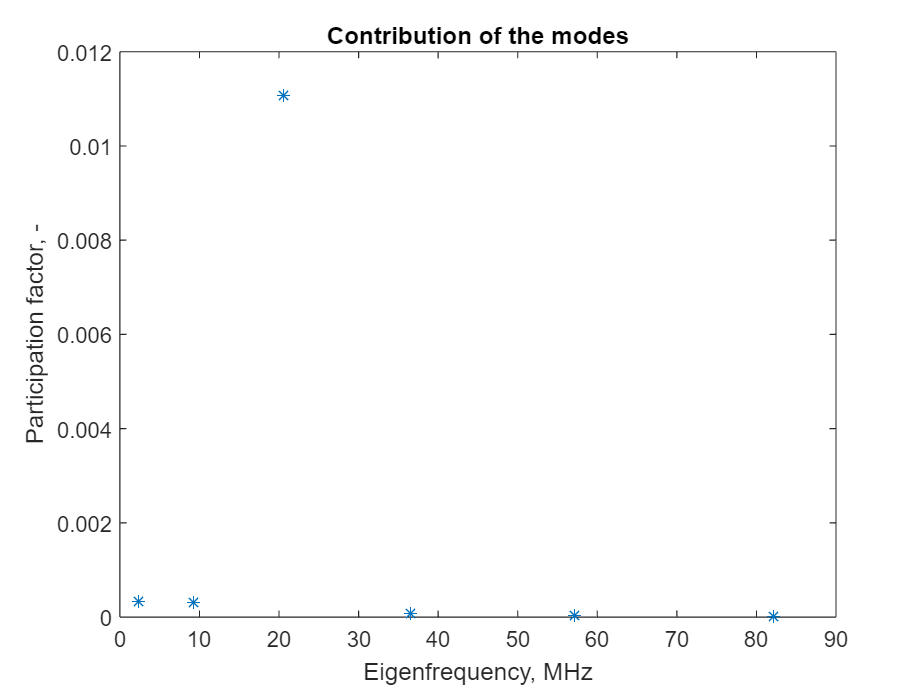

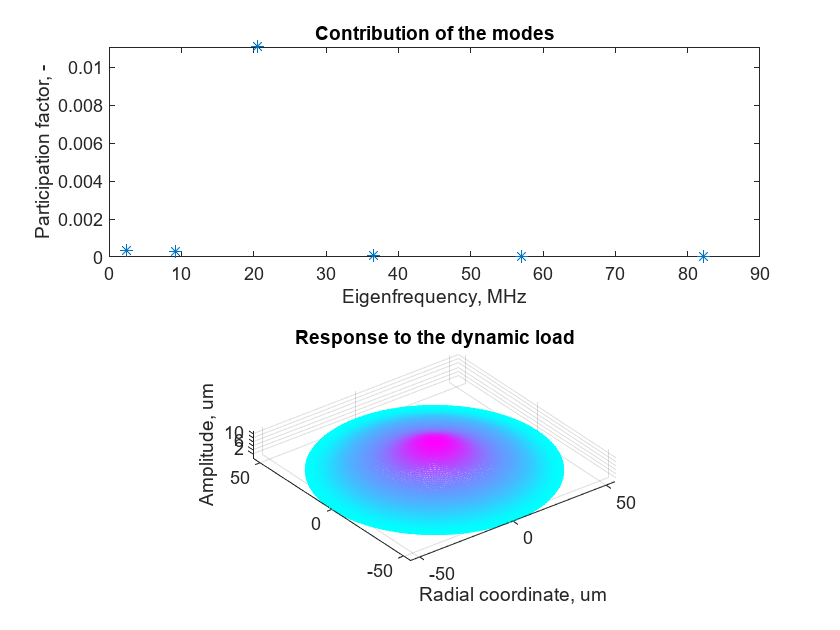

CMUT1 = Find_Response(CMUT1, V_dc_1, 5, 20.4);

plot(1e-6*CMUT1.Eigenfrequencies(1,:), 1e6*CMUT1.Amplitude_Response.dynamic.factors, '*')
title('Contribution of the modes')
xlabel('Eigenfrequency, MHz')
ylabel('Participation factor, -')
zlabel('Amplitude, um')

Plot_Response(CMUT1, 'Dynamic', '2D');

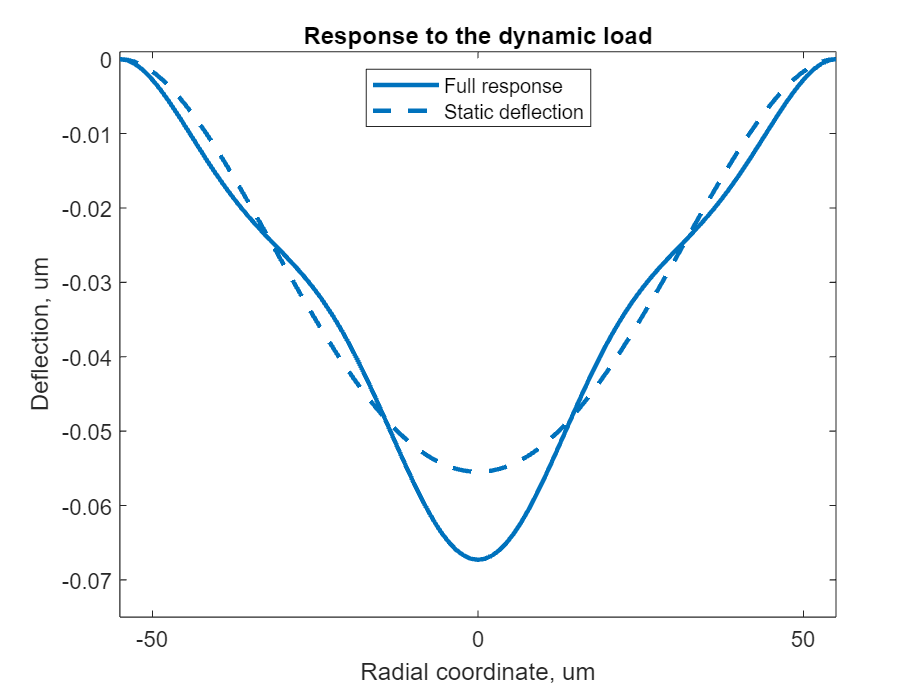


figure
plot(1e6*CMUT1.r,-1e6*CMUT1.Amplitude_Response.dynamic.amp(:,1,3), 'LineWidth', 2, 'Color',[0 0.4470 0.7410])
hold on
plot(1e6*CMUT1.r,-1e6*CMUT1.Amplitude_Response.dynamic.amp(:,1,1), '--', 'LineWidth', 2, 'Color',[0 0.4470 0.7410])
title('Response to the dynamic load')
xlabel('Radial coordinate, um')
ylabel('Deflection, um')
legend('Full response', 'Static deflection')
ylim([-0.075; 1e-3])
xlim([1e6*CMUT1.r(1); 1e6*CMUT1.r(end)])
legend('Full response', 'Static deflection', 'Location','north')
hold off

#### Sweep case

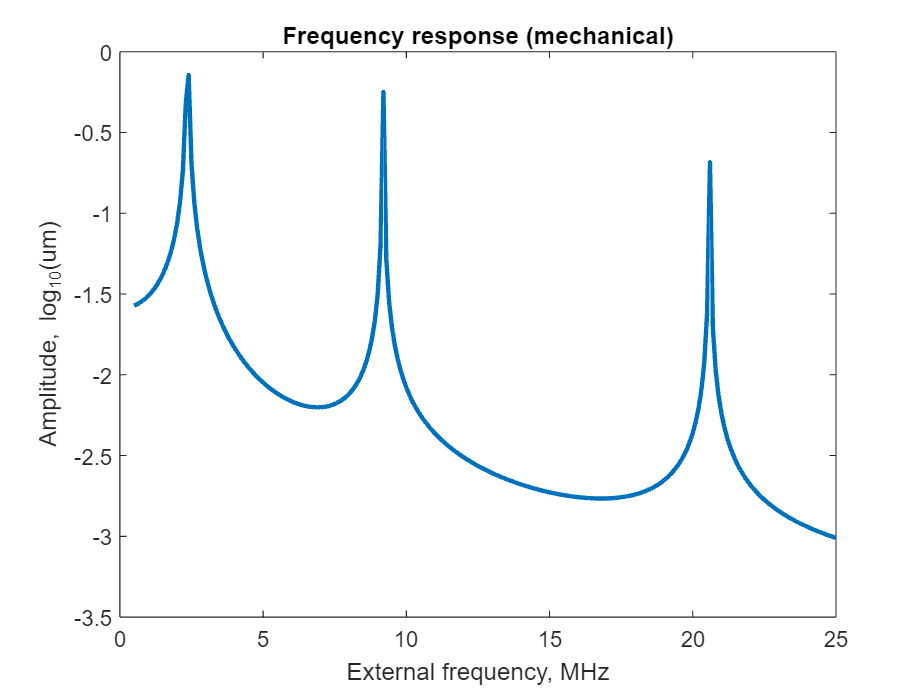

CMUT1 = Find_Response(CMUT1, V_dc_1, 5, (0.5:0.1:25)); 

Response = zeros(length(CMUT1.Amplitude_Response.sweep.f), 1);
dimension = 'Dynamic';
for i=1:length(CMUT1.Amplitude_Response.sweep.f)
    if strcmp(dimension,"Static") == 1
        Response(i) = CMUT1.Amplitude_Response.sweep.amp(ceil(CMUT1.N_r/2),1,i, 1);

    elseif strcmp(dimension,"Dynamic") == 1
        Response(i) = CMUT1.Amplitude_Response.sweep.amp(ceil(CMUT1.N_r/2),1,i, 2);

    elseif strcmp(dimension,"Full") == 1
        Response(i) = CMUT1.Amplitude_Response.sweep.amp(ceil(CMUT1.N_r/2),1,i, 3);
    else
        disp('"Static", "Dynamic" or "Full" sweep response types are supported')
    end
end

plot(1e-6*CMUT1.Amplitude_Response.sweep.f, log10( 1e6*abs(Response)), 'LineWidth', 2)
title('Frequency response (mechanical)')
xlabel('External frequency, MHz')
ylabel('Amplitude, log_{10}(um)')

## Acoustical response to an arbitrary excitation

#### Calculation of Rayleigh integral

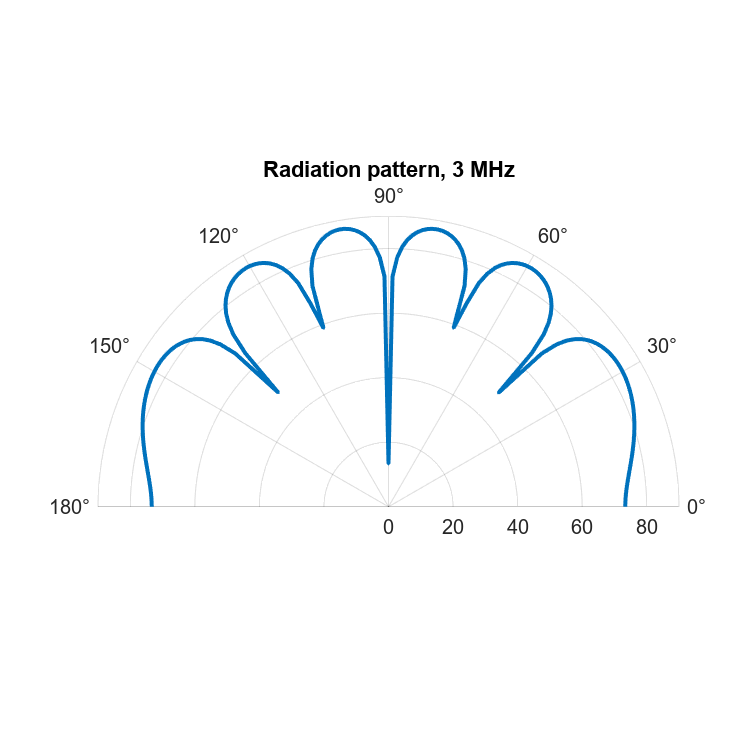

CMUT1 = Find_Response(CMUT1, V_dc_1, 5, 3);

N_x = 2;
N_y = 2;

Phase_shift = zeros(N_x,N_y);
Phase_shift(:,2) = 2*pi/2;

CMUT1 = Find_FR( CMUT1, 'Dynamic', N_x, N_y, Phase_shift, 6*CMUT1.R*1e6, 'air', 50000, [-1,0] );

if CMUT1.rho_medium == 1.2754
    p_ref = 20e-6;
elseif CMUT1.rho_medium == 997
    p_ref = 1e-6;
end

polarplot(CMUT1.Frequency_Response.RP.phi/180*pi,  10*log10((0.5*CMUT1.Frequency_Response.RP.p.*conj(CMUT1.Frequency_Response.RP.p))/p_ref^2), 'LineWidth', 2);
thetalim([0; 180])
title(['Radiation pattern, ' num2str(1e-6*CMUT1.Amplitude_Response.dynamic.f),' MHz'])

#### Calculation of acoustical frequency response

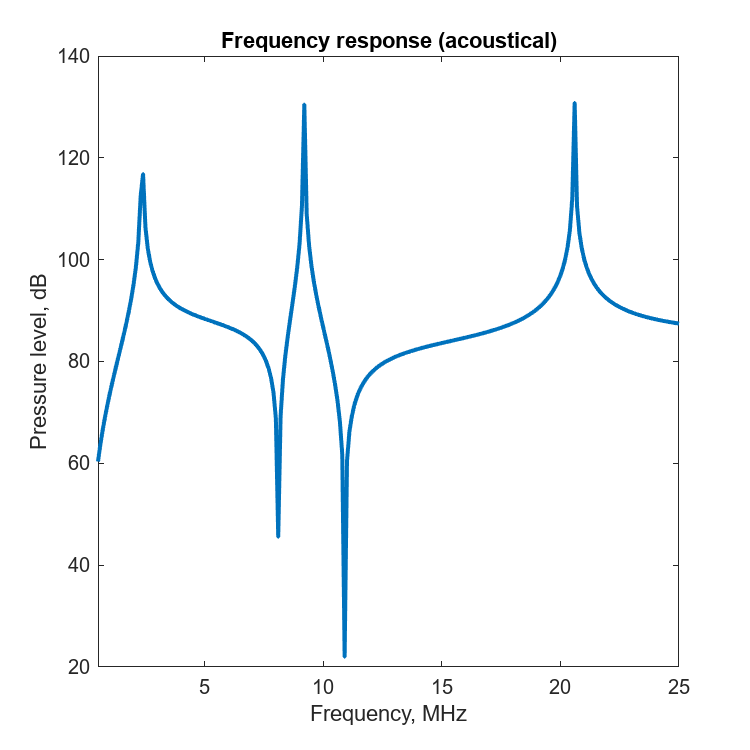

CMUT1 = Find_Response(CMUT1, V_dc_1, 5, (0.5:0.1:25)); 

CMUT1 = Find_FR( CMUT1, 'Sweep', 1, 1, Phase_shift, 3*CMUT1.R*1e6, 'air', 5000, [1,0] );

plot(1e-6*CMUT1.Frequency_Response.f, real(CMUT1.Frequency_Response.FR), 'LineWidth', 2)
title('Frequency response (acoustical)')
xlabel('Frequency, MHz')
ylabel('Pressure level, dB')
xlim(1e-6*[CMUT1.Frequency_Response.f(1); CMUT1.Frequency_Response.f(end)])